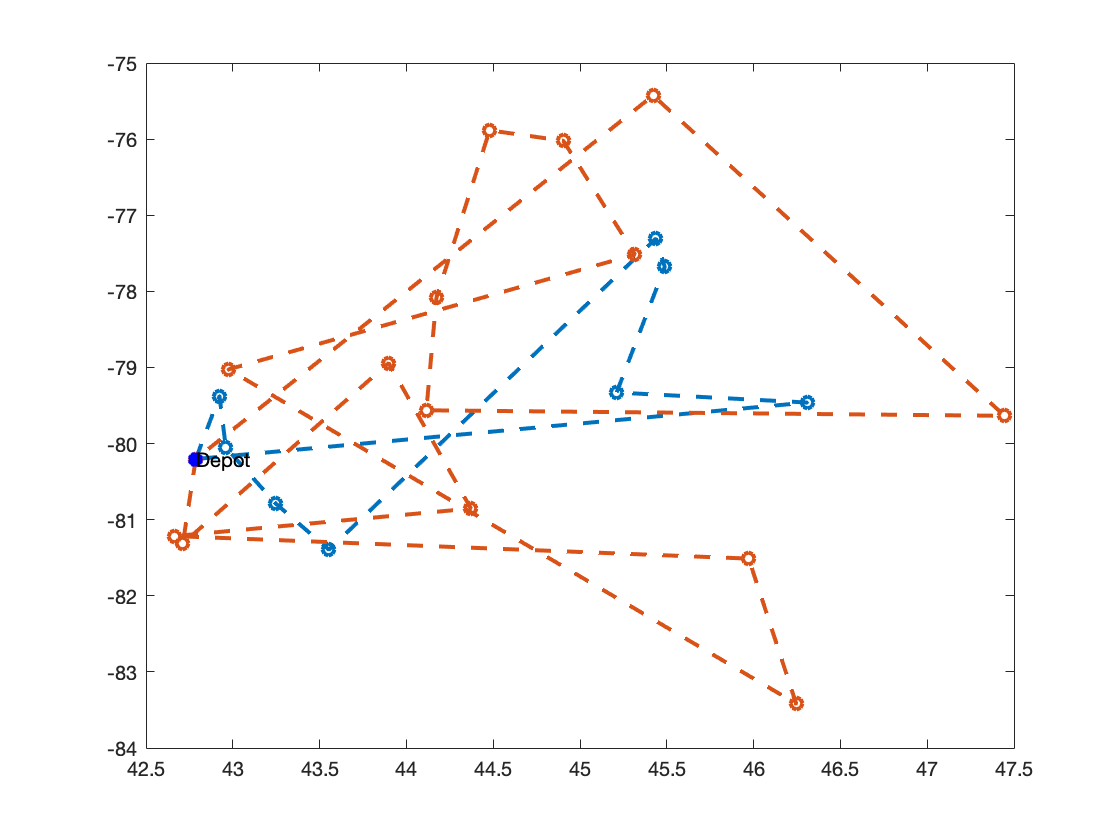

clear all;
clc;
C0=load('c_23.csv'); % depot+clients
C0Size=size(C0);
C=C0(2:C0Size(1),:);
C_N=size(C,1);
V_N=2;
% define C_N*C_N matrix to store the distance between tow cities.
D_C=[];
D_C=load('d_100.csv');
max_capacity=2000;
% for i=1:size(C0,1)
% for j=1:size(C0,1) 
%   %D_C(i,j)=i+j;
%   D_C(i,j)=sqrt((C0(i,2)-C0(j,2)).^2+(C0(i,3)-C0(j,3)).^2);
% end
% end
% initialize
popSize=200;
empty_pop.routes=zeros(V_N,C_N);
empty_pop.clients=[];
empty_pop.distances=[];
empty_pop.total_distance=0;

pop=repmat(empty_pop,popSize,1);
for i=1:popSize
    pop(i)=completion(pop(i),C_N,V_N,C,D_C,max_capacity);
end
%% sort pop by totalDistance from min to max 
for i=1:popSize
    for j=1:i
        if pop(j).total_distance>pop(i).total_distance
            temp=pop(i);
            pop(i)=pop(j);
            pop(j)=temp;
        end
    end
end
%% process
pc=0.8;
pm=0.08;
max_NFC=200;
numberofcrossover=round(pc*popSize); 
numberofmutation=round(pm*popSize);
numberofrec=popSize-(numberofcrossover+numberofmutation);
for i=1:max_NFC
    pop2=repmat(empty_pop,0,1);
    % selecting population for crossover     
    selected=repmat(empty_pop,numberofrec,1);
    for j=1:numberofrec
        selected(j)=pop(j); 
        pop2(end+1)=pop(j);
    end
    
    %% crossover   
    c=randperm(popSize);
    individualsForCross=repmat(empty_pop,numberofcrossover,1);
    for j=1:numberofcrossover
           individualsForCross(j)=pop(c(j));
    end
    % crossover of parent1 and parent2
    offspringset=repmat(empty_pop,0,1);   
    for z=1:numberofcrossover   
        n_parent1=ceil(numberofcrossover*rand);
        n_parent2=ceil(numberofcrossover*rand);
        parent1=individualsForCross(n_parent1);
        parent2=individualsForCross(n_parent2);
        crossoverpoint=ceil((C_N-1)*rand);
        parent12=parent1.clients(1:crossoverpoint);
        parent21=parent2.clients(1:crossoverpoint);
        s1=[];
        s2=[];
        for j=1:numel(parent1.clients)
            if sum(parent1.clients(j)~=parent21)==numel(parent21)
                s2=[s2 parent1.clients(j)];
            end
            if sum(parent2.clients(j)~=parent12)==numel(parent12)
                s1=[s1 parent2.clients(j)];
            end
        end
        offspring1=repmat(empty_pop,1,1);
        offspring2=repmat(empty_pop,1,1);
        offspring1.clients=[parent12 s1];
        offspring2.clients=[parent21 s2];
     
        % evaluate fitness
        offspring1=completion(offspring1,C_N,V_N,C,D_C,max_capacity);
        offspring2=completion(offspring2,C_N,V_N,C,D_C,max_capacity);        
         offspringset(end+1)=offspring1;
         offspringset(end+1)=offspring2;
         pop2(end+1)=offspring1;
         pop2(end+1)=offspring2;
    end
    %% Mutation    
     % selecting a parent for mutation
    m=randperm(popSize);
    individualsForMutation=repmat(empty_pop,numberofmutation,1);
    for j=1:numberofmutation
        individualsForMutation(j)=pop(m(j));
    end       
    %doing the mutation
    Mutatedset=repmat(empty_pop,0,1);
    for z=1:numberofmutation
        parent=individualsForMutation(z).clients;        
        mutationPoint1=ceil(C_N*rand);
        mutationPoint2=ceil(C_N*rand);
        temp=parent(mutationPoint1);
        parent(mutationPoint1)=parent(mutationPoint2);
        parent(mutationPoint2)=temp;           
        % Evaluate fitness of mutateed members       
        mutated_parent=repmat(empty_pop,1,1);
        mutated_parent.clients=parent;       
        mutated_parent=completion(mutated_parent,C_N,V_N,C,D_C,max_capacity);
        Mutatedset(end+1)=mutated_parent; 
        pop2(end+1)=mutated_parent;
    end
    %sort the new population     
    for z=1:size(pop)
        for j=1:z
            if pop(j).total_distance>pop(z).total_distance
                temp=pop(z);
                pop2(z)=pop(j);
                pop2(j)=temp;
            end
        end
     end
    %find the best root    
    for j=1:popSize
        pop(j)=pop2(j);
    end
end
best=pop(1);
%% plot
figure;
color=['r','g','b','c','m','y','k','w'];
routes=best.routes;
for i=1:V_N
route=routes(i,:);
X=C0(1,2);
Y=C0(1,3);
for j=1:numel(route)
    if route(j)~=0
        X(j+1)=C(route(j),2);
        Y(j+1)=C(route(j),3);
    end
end    
X=[X,C0(1,2)];
Y=[Y,C0(1,3)];
plot(X,Y,'--',"Marker","o",'LineWidth',2);
hold on;
end
plot(C0(1,2),C0(1,3),'*','Color','b',"LineWidth",10);
text(C0(1,2),C0(1,3),'Depot');
%title("Figure 1");
hold off;

function chromsome=completion(chromsome,C_N,V_N,C,D_C,max_capacity)
    satisfy_capacity=0;
    while satisfy_capacity==0
        x=randperm(C_N);
        chromsome.clients=x;
        chromsome.routes=[];
        %divide into V_N routes
        indexs=randperm(C_N,V_N-1);
        indexs_order=sort(indexs);
        d_sum=0;
        flag=0;
        for j=1:V_N
            if(j==V_N)
                if indexs_order(j-1)==C_N
                    start_p=C_N;
                else
                start_p=indexs_order(j-1)+1;
                end
                end_p=C_N;
            else
                index=indexs_order(j); % 5,9       
                start_p=1;
                end_p=index;
                if j~=1            
                    index_1=indexs_order(j-1);
                    start_p=index_1+1;
                end 
            end
            s=chromsome.clients(1,start_p);
            e=chromsome.clients(1,end_p);
            d=D_C(C(s,1),1);  % distance from first client to depot 
            d2=D_C(C(e,1),1); % distance from last client to depot
            for k=start_p:end_p-1
                
                C_index=chromsome.clients(1,k);
                C_index_next=chromsome.clients(1,k+1);
                d=d+D_C(C(C_index,1),C(C_index_next,1));
            end
            chromsome.distances(j)=d;
            d_sum=d_sum+d+d2;
            %vehicle route 
            r=[];
            %vehicle capacity
            demand=0;
            for n=start_p:end_p
                C_index=chromsome.clients(1,n);
                r=[r,C_index];
                demand=demand+C(C_index,4);
            end
            if(demand>max_capacity)
                break;
            else
                flag=flag+1;
            end                       
            for m=1:numel(r)
                chromsome.routes(j,m)=r(m);
            end             
        end
        chromsome.total_distance=d_sum;
        % check the demand
        if(flag==V_N)
            satisfy_capacity=1; 
            break;
        end    
        
    end
end